# CÓDIGO DESENVOLVIDO BASEADO NO MÉTODO DOS ELEMENTOS FINITOS UTILIZANDO A FORMULAÇÃO GUF 

# CLEANING

% clc; clear; close all

## APPROXIMATION

APP = [4 4 4]; 

## MESH

nel = 6;
mesh.ney = nel; % number of elements in Y
mesh.nex = nel; % number of elements in X
mesh.Lx = 1;   % length in X 
mesh.Ly = 1;   % length in Y
fprintf('a = %d',mesh.Lx)

a = 1

fprintf('b = %d',mesh.Ly)

b = 1

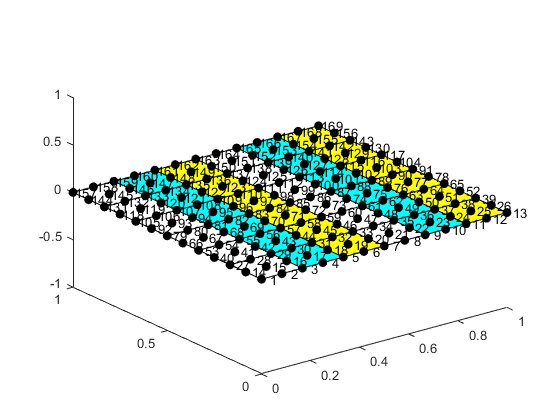

mesh.type = 'Q9';
[ mesh ] = create_mesh( mesh );

## THEORY

theory = 'EQ'; % EQ - Equivalent Single Layer
               % LW - Layerwise
               if strcmp(theory,'EQ')
                   fprintf('Equivalent Single Layer')
               elseif strcmp(theory,'LW')
                   fprintf('Layerwise')
               end

Equivalent Single Layer

## MATERIAL - ISOTROPIC

mat(1).E = 10920; % YOUNG MODULUS
mat(1).nu = 0.3;  % POISSON RATIO

## GEOMETRY

geo(1).h = 0.01;         % THICKNESS
geo(1).z_top = geo(1).h/2;
geo(1).z_low =-geo(1).h/2;
geo(1).theta = 0;     % ANGLE
NL = length(geo);     % NUMBER OF LAYERS

## DEGREES OF FREEDOM

[ dof ] = degrees_of_freedom( APP, mesh, NL, theory );


Layer has 5 degrees of freedom in X direction 
Layer has 5 degrees of freedom in Y direction 
Layer has 5 degrees of freedom in Z direction 

Laminate has 5 degrees of freedom in X direction 
Laminate has 5 degrees of freedom in Y direction 
Laminate has 5 degrees of freedom in Z direction 


## BOUNDARY CONDITIONS

typeofBC = 'ssss'; % 'ssss' = Simply supported
                   % 'cccc' = Clamped
if strcmp(typeofBC,'ssss')
    fprintf('Simply supported plate')
elseif strcmp(typeofBC,'cccc')
    fprintf('Clamped plate')
end

Simply supported plate

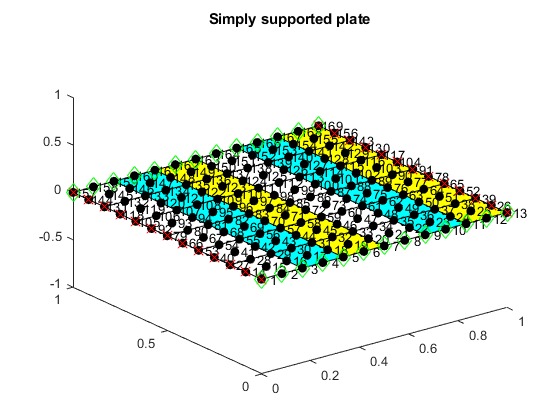


[ fixedNode ] = Boundary_Condition( mesh, typeofBC );

[ dof ] = free_DOF( dof, fixedNode, mesh  );

## APPLIED PRESSURE

type_Load = 'uniform'; % UNIFORM LOAD = uniform
                       % SINUSOIDAL LOAD = sinusoidal
%    X Y Z
P = [0 0 1E-3;  % TOP
     0 0 0]; % BOTTOM

## COMPUTING GLOBAL STIFFNESS

for ply = 1 : NL
    % COMPUTING PLY STIFFNESS
    [ stiffness ] = classic_Hook_iso( mat, geo, ply );
    
    %COMPUTING KERNELS
    [ Z ] = z_matrix( APP, geo, ply, stiffness, theory );
    [ S ] = shape_function( mesh );
    KE = local_stiffness( dof, mesh, S, Z );
end
clear Z stiffness S
[ KG ] = global_stiffness_matrix( dof, KE, mesh );

## COMPUTING LOAD VECTOR

[ D ] = D_matrices( geo, dof, theory, NL );
switch type_Load
    case 'sinusoidal'
        [ Fg ] = sinusoidal_load( dof, mesh, D, P );
    case 'uniform' 
%         [ Fg ] = uniform_load( dof, mesh, D, P );
    [ Fg ] = uniform_load( dof, mesh, D, P );
end
clear D

## COMPUTING DISPLACEMENT

U = zeros(size(KG,1),1);
U(logical(dof.free),1) = sparse(KG(logical(dof.free), logical(dof.free)))\sparse(Fg(logical(dof.free), 1));
en = U'*Fg;

## POST-PROCESSING

Displacement in z direction (at z/h = 1/4) = 0.000000


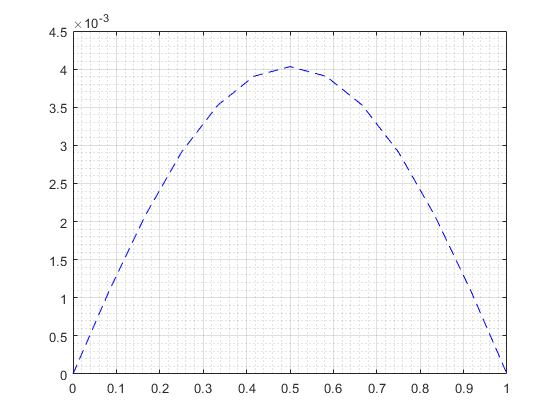

post_processing( dof, geo, mesh, U )

% [ sigma ] = stresses_plate( APP, dof, geo, mesh, stiffness, U, 0 )